wordfile = export('hw96.mlx')

wordfile = 'C:\Users\jesse\Documents\MATLAB\Numerical Methods\Homework9.6\hw96.pdf'

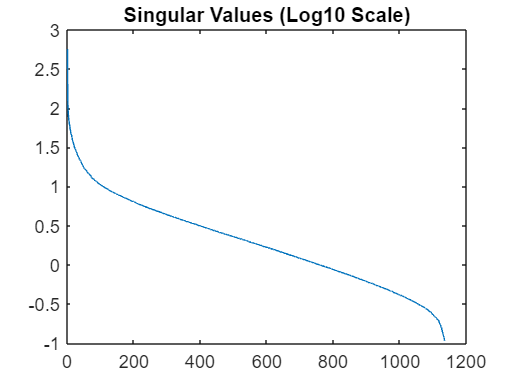

clear, clc
% Read the picture of the tiger, and convert to black and white.
palace = rgb2gray(imread('GarnierPalace.png'));

% Downsample, just to avoid dealing with high-res images.
palace = im2double(imresize(palace, 0.5));
x = numel(palace);



% Compute SVD of this tiger
[U, S, V] = svd(palace);

% Plot the magnitude of the singular values (log scale)
sigmas = diag(S);
figure; plot(log10(sigmas)); title('Singular Values (Log10 Scale)');

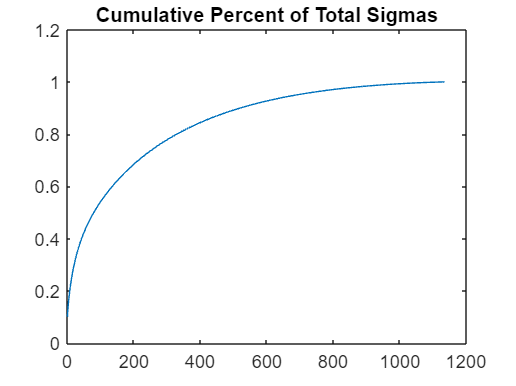

figure; plot(cumsum(sigmas) / sum(sigmas)); title('Cumulative Percent of Total Sigmas');

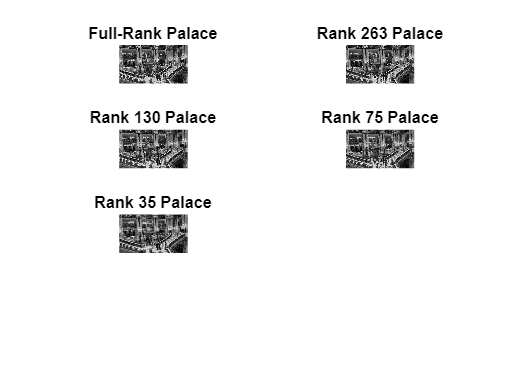


% Show full-rank tiger
figure; subplot(4, 2, 1), imshow(palace), title('Full-Rank Palace');

%show 75% palace


% Compute low-rank approximations of the tiger, and show them
percent75 = 263;
percent50 = 130;
percent25 = 75;
percent0 = 35;
ranks = [percent75, percent50, percent25, percent0];
for i = 1:length(ranks)
    % Keep largest singular values, and nullify others.
    approx_sigmas = sigmas; approx_sigmas(ranks(i):end) = 0;

    % Form the singular value matrix, padded as necessary
    ns = length(sigmas);
    approx_S = S; approx_S(1:ns, 1:ns) = diag(approx_sigmas);
    
    

    % Compute low-rank approximation by multiplying out component matrices.
    approx_palace = U * approx_S * V';
    y = numel(approx_palace);
    
  


    % Plot approximation
    subplot(4, 2, i + 1), imshow(approx_palace), title(sprintf('Rank %d Palace', ranks(i)));
end